# Projet 4.5 - Séparation de sources Audio

## Représentation parcimonieuse et acquisitions compressées

Fichier .mlx permettant de tester deux ou trois idées.

Attention, faites en sorte d'avoir :

- Audio Toolbox (Pour importer du son et tout c'est mieux)

- Signal Processing Toolbox 

- Wavelet toolbox (Pour générer les dictionnaires (?))

- Statistics and Machine Learning Toolbox (Pour les algorithmes spécifiques txpe ICA, clustering, etc..)

- RIP l'espace libre sur vos disques durs.

## Étape 1 - Avoir une source et la caractériser

Déjà, on va ouvrir un signal sur matlab. 

On peut utiliser n'importe quel signal audio. Ici, je ne prendrai que les 20 premières secondes d'un signal , 

dans le souci de soulager nos processeurs, déjà très sollicités par l'UI de Matlab.

J'ai P=2 observations de mon mélange (les deux mono qui forment le stereo), et 3 sources.

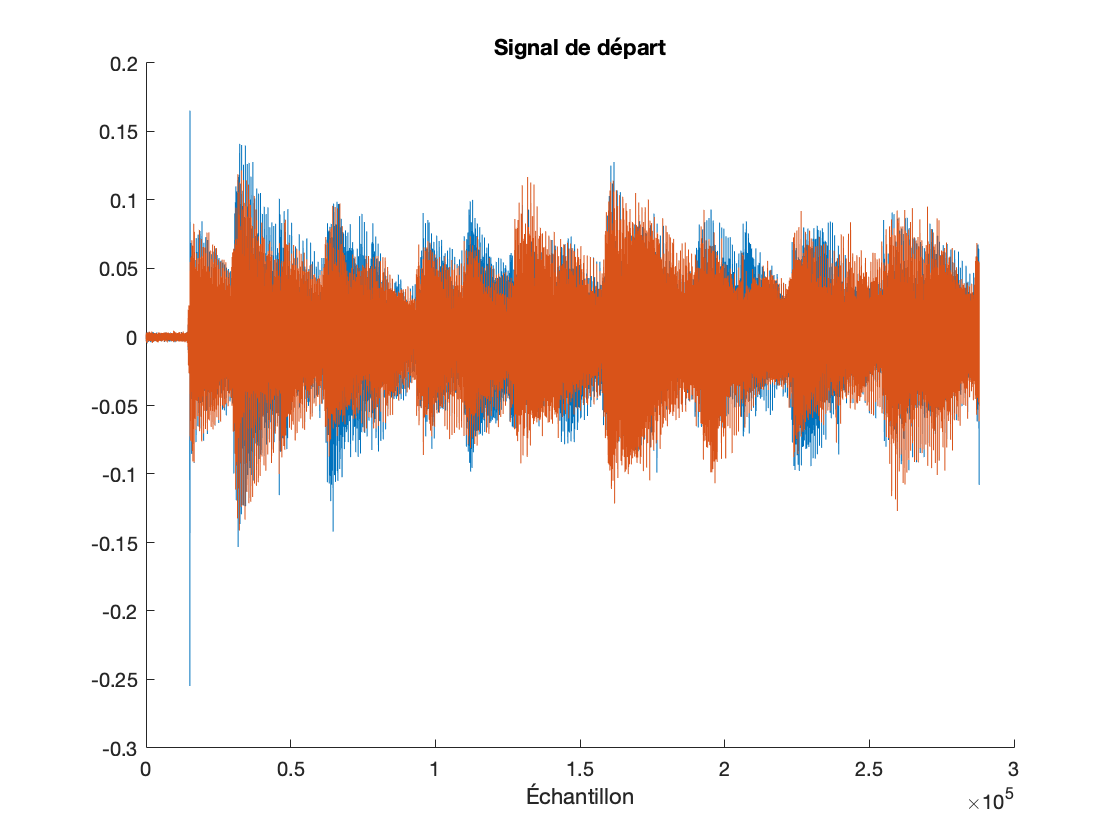

clear all
[~,Fs] = audioread('3_voix 2.0.wav');
samples = [1,6*Fs];     %Je ne prends que les 10 premières secondes, sinon mon ordi est à la rue
clear y Fs
[x,Fs] = audioread('3_voix 2.0.wav',samples);




x1 = x(:,1);  %J'ai séparé les deux signaux, parce que Stereo
x2 = x(:,2);
%x1 = x1(1:4:end);
%x2 = x2(1:4:end);

%x = [x1, x2];

%Nombre d'éléments du signal
T = length(x);
%Durée d'observation, en secondes
Tobs = T / Fs;
%Plot
figure;
title('Signal de départ')
xlabel("Échantillon")
hold on;
plot(x1);
plot(x2)
hold off



[s1, Fs] = audioread("bass.wav", samples);

[s2, Fs] = audioread("chords.wav", samples);

[s3, Fs] = audioread("arpeges.wav", samples);
%Ce sont nos sources au départ, ça peut servir


s1 = s1(:,1);

s2 = s2(:,1);
s3 = s3(:,1);
        %Je ne prends qu'un canal
        
        
S(1,:)=s1;
S(2,:)=s2;
S(3,:)=s3;  %On génère notre matrice permettant d'avoir une fenetre avec le code tout fait




## Étape 2 - Parcimonier... si on peut le dire comme ça.

Je vais maintenant transformer ce sur quoi je travaille. En effet, je vais passer dans un autre domaine, et utiliser la ***modified discrete cosine transform. ***

On qualifiera cette transformée de ***sparsifying linear transform --> ***Elle va rendre nos données parcimonieuses, ou du moins on l'espère. 

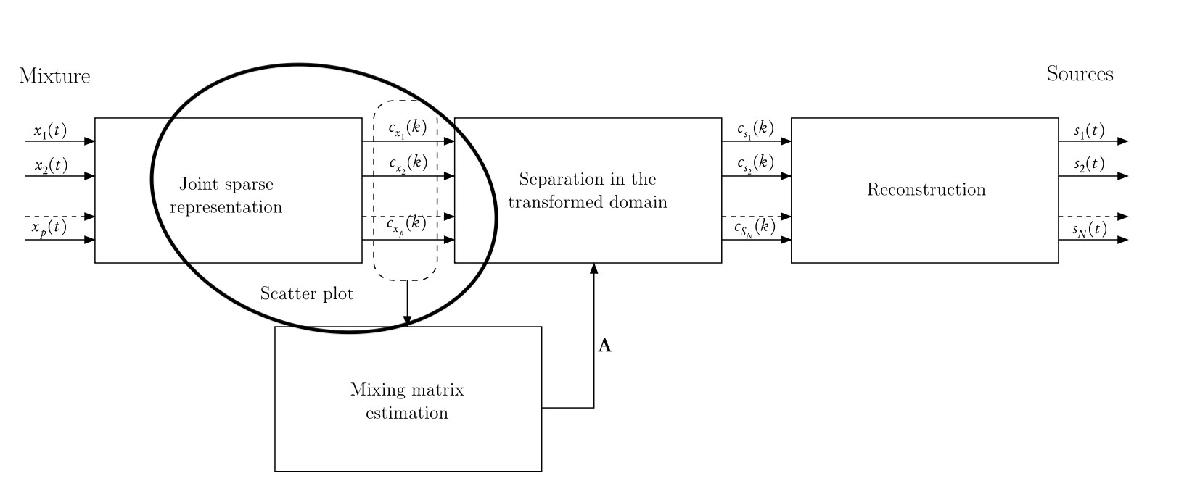

En effet, dans les faits les signaux audio sont tout sauf parcimonieux à la base. 

C'est un problème à dominantes multiples (Les sources sont actives simultanément), ce qui rend la chose bien plus difficile.  

*Tester d'autres sparsifxing transform, peut être? *

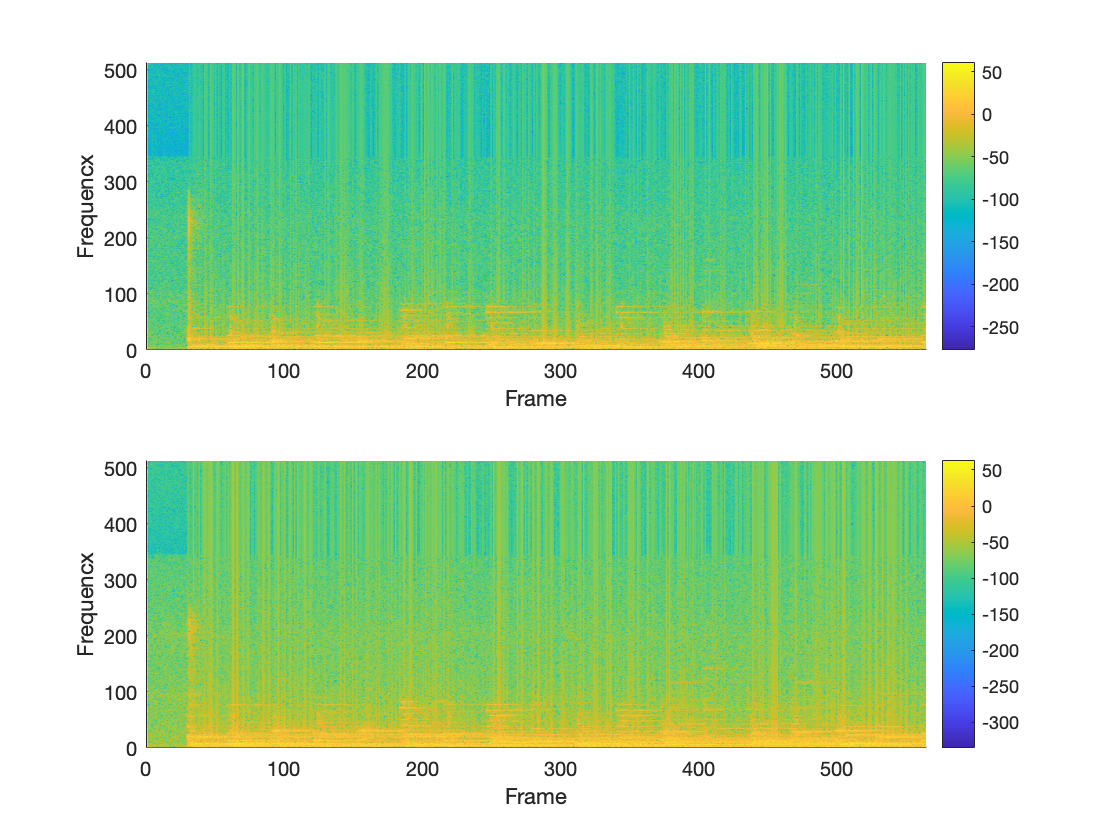

win_size = 1024; 
% On peut déjà commencer par une fenêtre rectangulaire. 
win = rectwin(win_size);
overlap = win_size - 8;   

[F_S, Frame_index] = bss_make_frames(x',win',0);


cx1 = mdct(x1,win);   % kbdwin renvoie une matrice de la taille de la fenetre sur 2 par
                                            %   ceil(2*length(x1)/1024) +1 
cx2 = mdct(x2, win);
coeff_size = size(cx1);  %Permet de se rendre compte que mdct renvoie une matrice, allez savoir..






subplot(2,1,1);
surf(20*log10(cx1.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequencx')
axis([0 size(cx1,2) 0 size(cx1,1)])
colorbar
subplot(2,1,2);
surf(20*log10(cx2.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequencx')
axis([0 size(cx2,2) 0 size(cx2,1)])
colorbar

Tracer l'histogramme permet de voir si on a une distribution parcimonieuse.

 cf 10.3 du Chap 10 - Handbook blind source separation

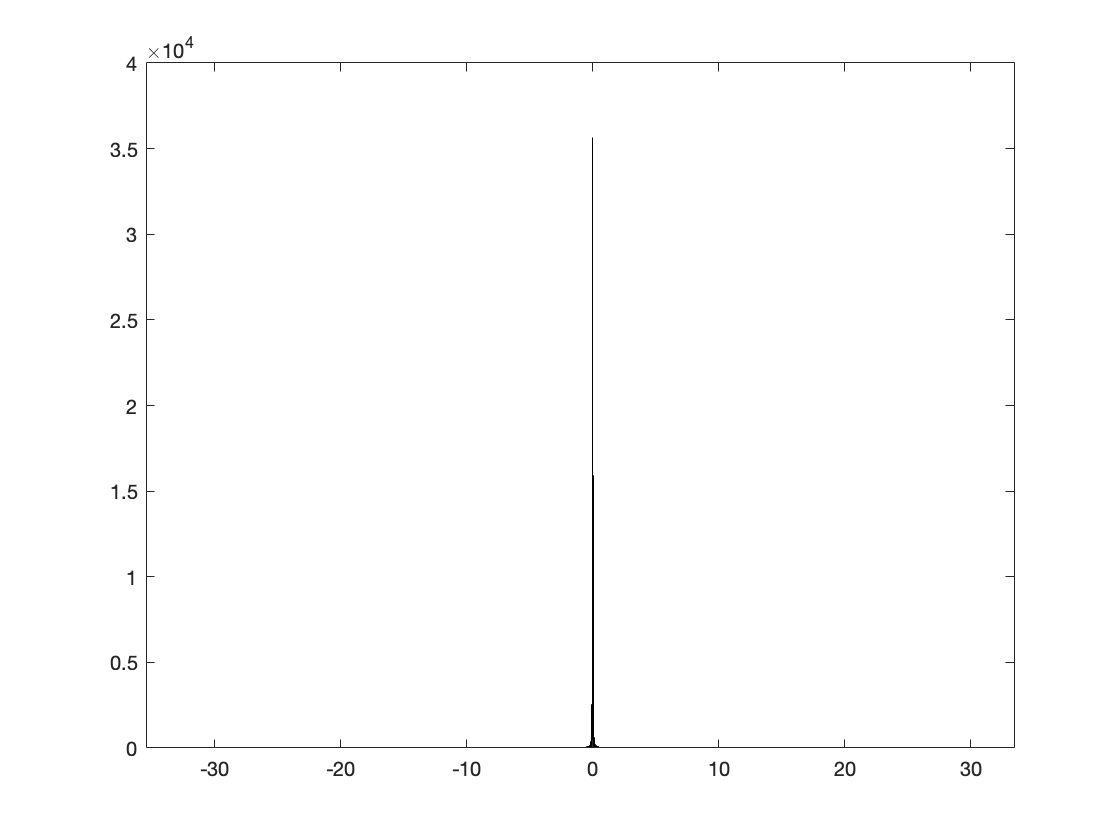

figure;
histogram(cx1,10000);    %Assez peu représentatif, on ne se rend pas bien compte

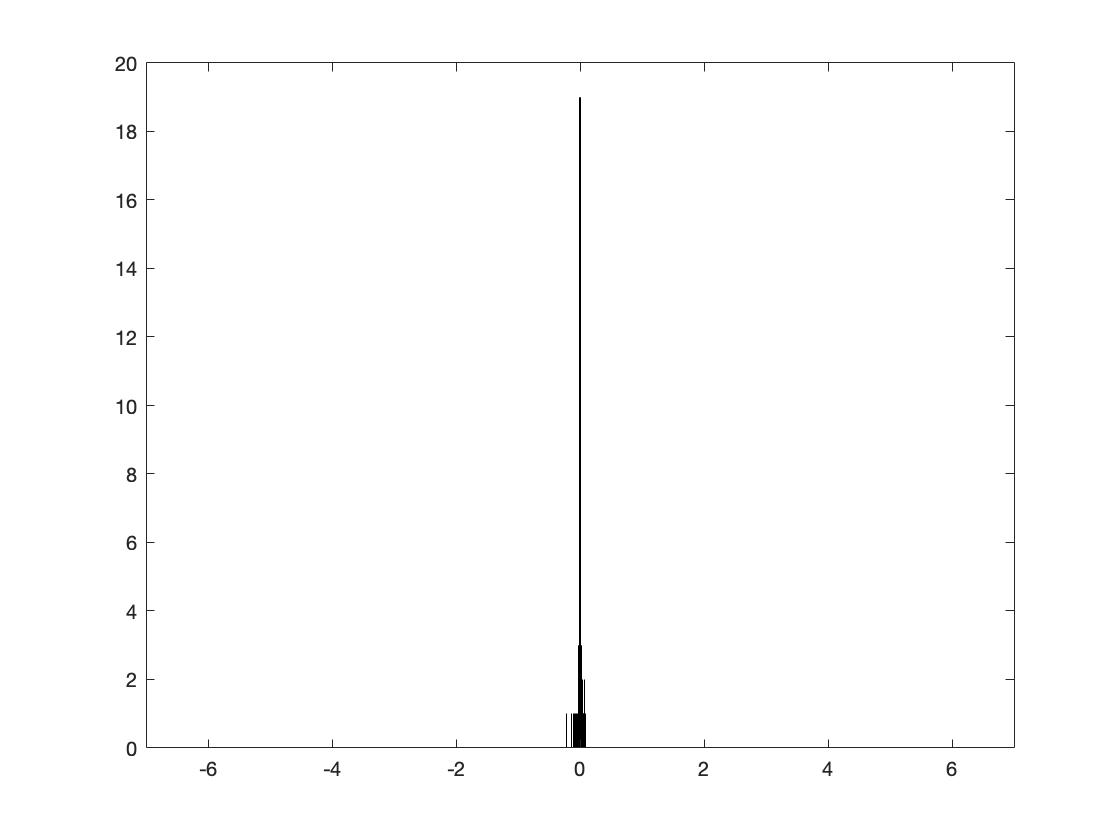

                            % de ce qu'il se passe dans voisinage plus petit de 0
figure;  %Pour regarder de plus près autour de 0
histogram(cx1(1:500),1000);
xlim([-7 7])

**Etant donné qu'on a pic pour des valeurs très petites, on peut se dire que c'est le cas : **

**on a plein de valeurs considérées comme quasi-nulles. **

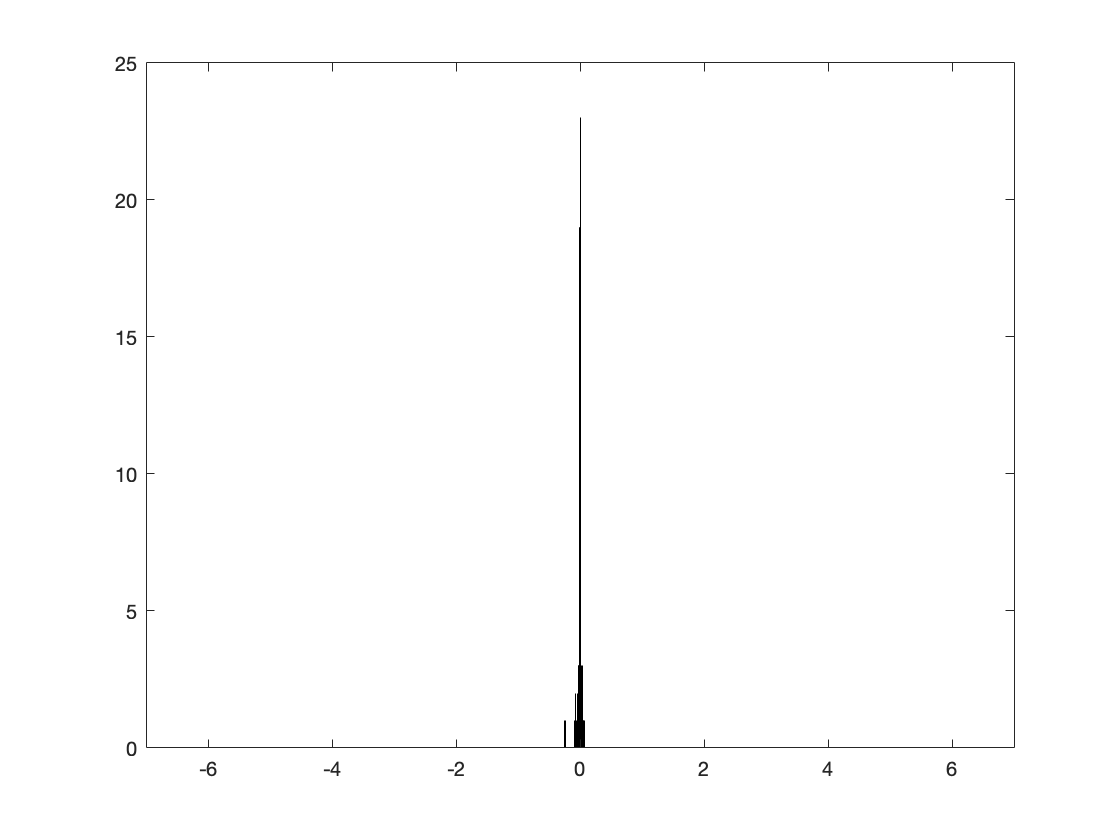

figure;  %Pour regarder de plus près autour de 0
histogram(cx2(1:500),1000);
xlim([-7 7])


temp = ceil(2*length(x1)/1024) + 1 ;
c1 = reshape(cx1,[win_size*temp/2,1]);

c2 = reshape(cx2,[win_size*temp/2,1]);    


Des plots non-interprétable pour l'instant.

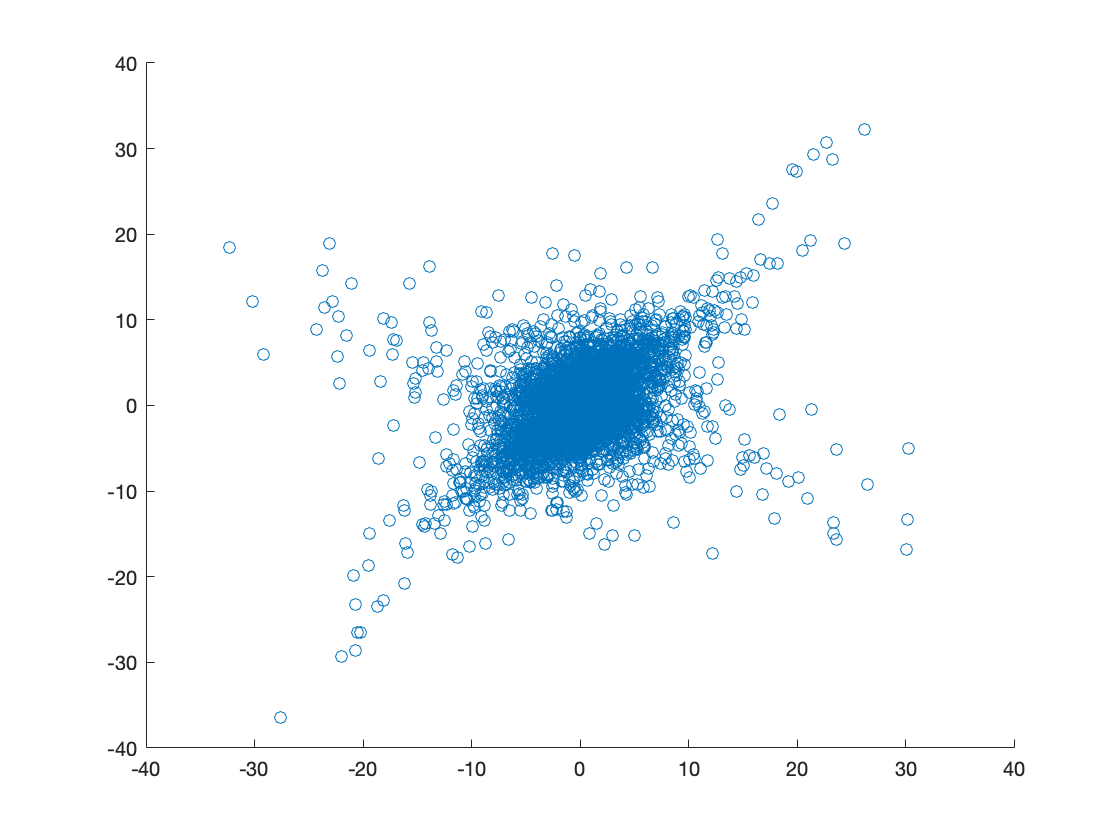

figure;
scatter(c1,c2);

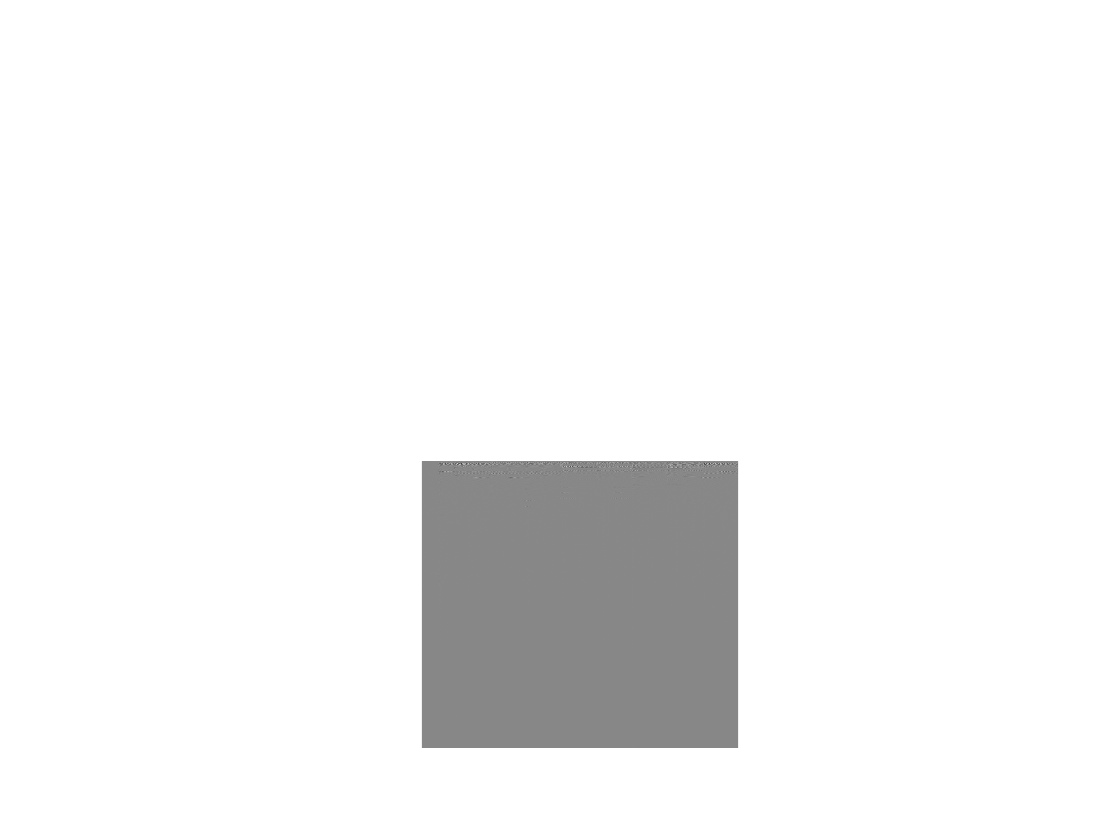

M1 = mat2gray(cx1);

M2 = mat2gray(cx2);

subplot(2,1,2);
imshow(M1);
subplot(2,1,2);
imshow(M2);

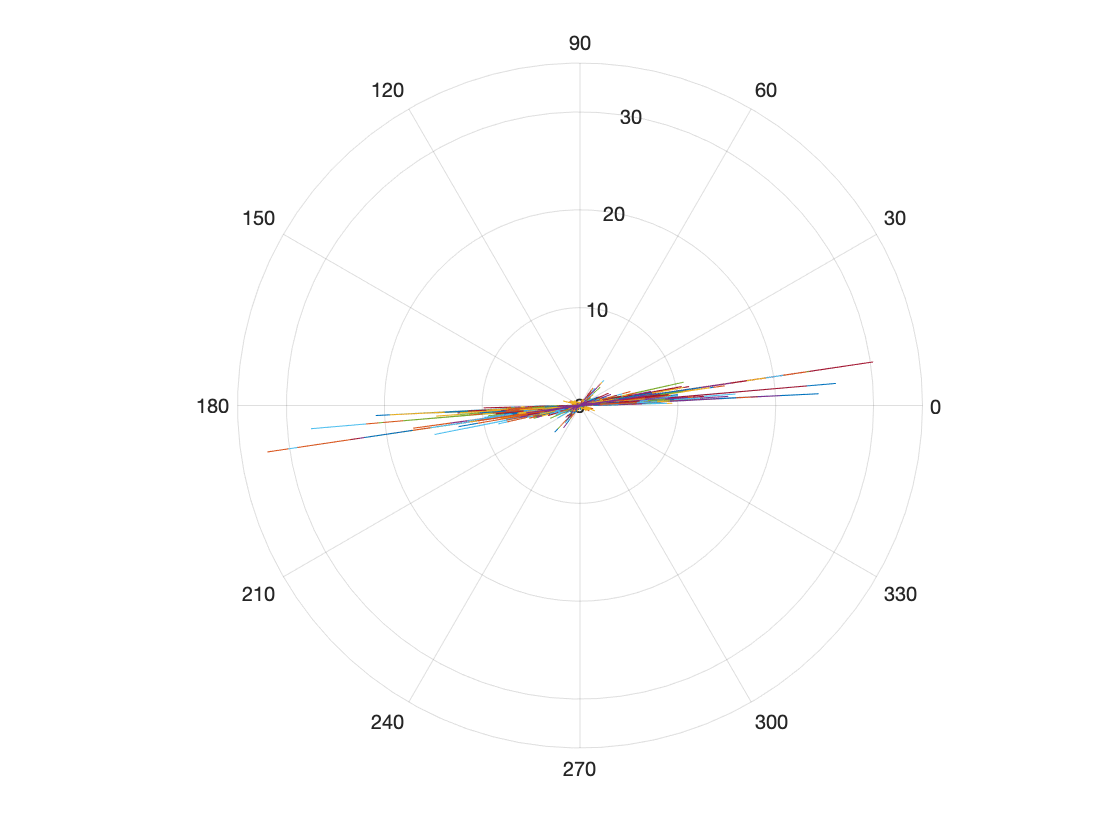

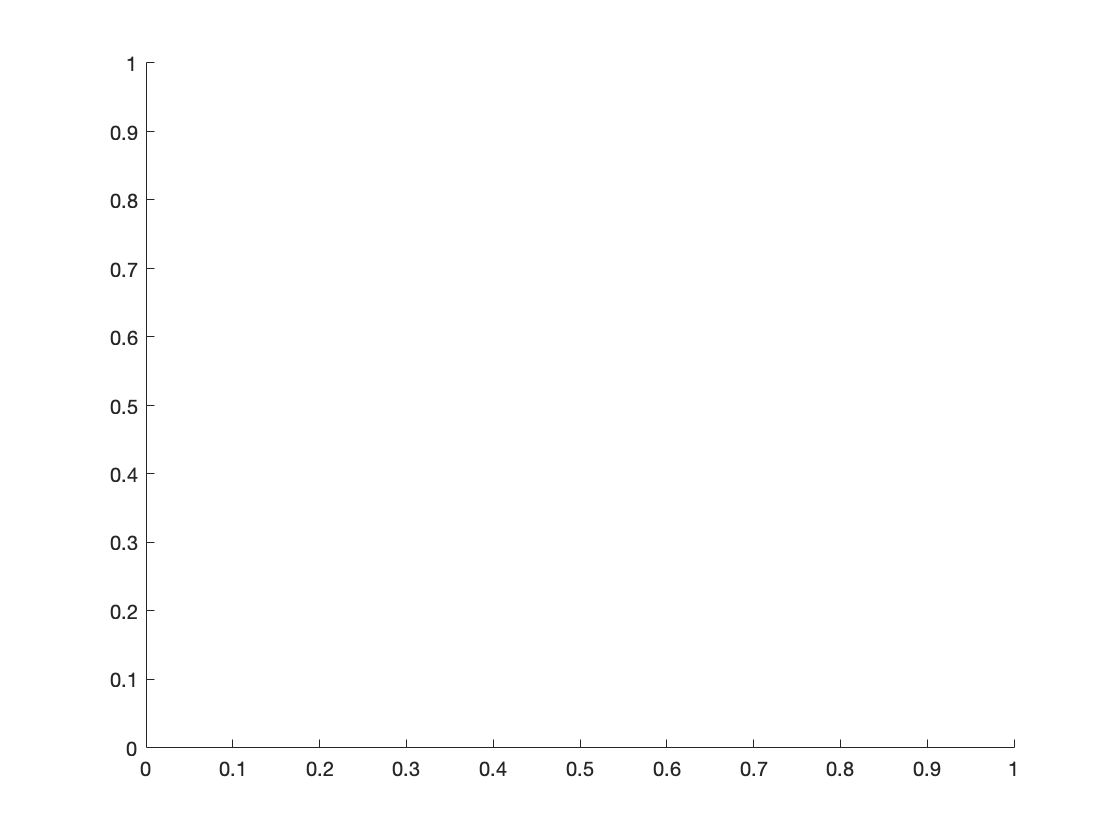

figure;
polarplot(cx1);

## Étape 3 - Estimation de la *Mixing Matrix*

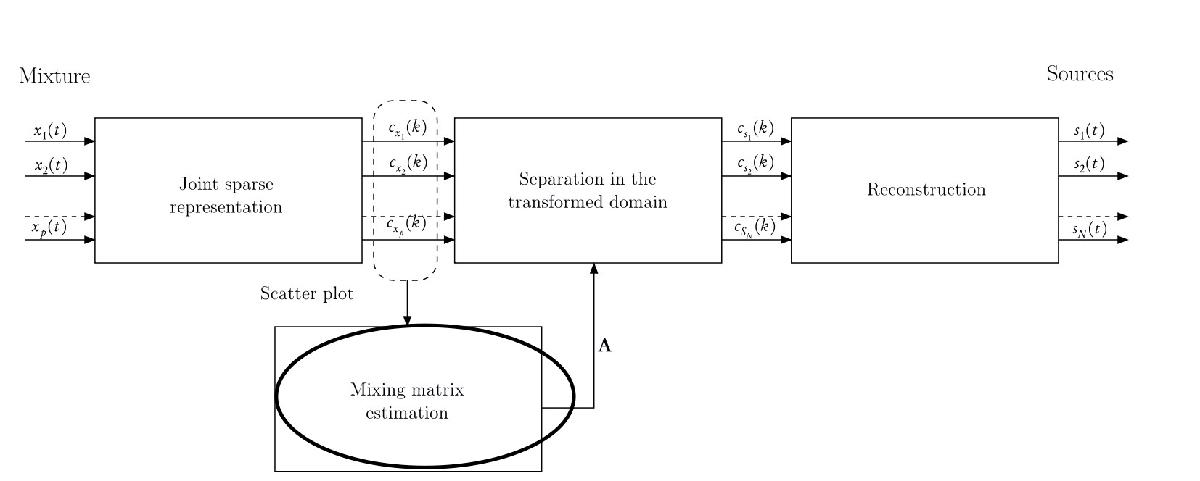

On doit ici estimer la mixing matrix, mais qu'est-ce donc que cela ?

Une matrice, certainement. C'est la matrice qui va représenter le mélange de nos différentes sources, qui composent notre signal final. 

%On va donner le dictionnaire

M = mdct(exe(temp),kbdwin(1024)); %Ne donne pas une matrice 2D.. mais 3D ?! 

%J'ai un gros doute quant à mon utilisation de mdct, et de la fenetre
%kbdwin par défaut.. Il faudra demander aux profs.``

TEST = imdct(cx1,kbdwin(win_size));



## Étape 4 - Séparation en composantes indépendantes

Selon le 2- du 10.1 du Chap 10 - Handbook blind source separation,

on peut appliquer un clustering algorithm sur le scatter plot (Mais le scatter plot de quoi?), mais habituellement, on utilise plutôt un algorithme de ICA (independent components analxsis). 

J'ai chopé des petites vidéos xt sxmpa dessus.

## Étape 5 - Reconstrucion de chaque composante